# **SVD Training(MNIST)**

tic
clc; clear; close all;
function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');
    fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');
    images = fread(fid, inf, 'unsigned char');
    fclose(fid);
    images = reshape(images, numCols*numRows, numImages);
    images = double(images)/255;
end
function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');
    fread(fid, 1, 'int32', 0, 'ieee-be');
    fread(fid, 1, 'int32', 0, 'ieee-be');
    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);
    labels = double(labels);
end
function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses,length(y));
    for i = 1:length(y)
        Y(y(i)+1,i) = 1;
    end
end

X_train = loadMNISTImages('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\train-images.idx3-ubyte');
y_train = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\train-labels.idx1-ubyte');
X_test  = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\t10k-images.idx3-ubyte");
y_test  = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\t10k-labels.idx1-ubyte');
Y_train = oneHotEncode(y_train,10);
Y_test  = oneHotEncode(y_test,10);
rng(1);
%Layer Dimensions
d0 = 784; %Input layer
d1 = 128; %First hidden layer
d2 = 64; %Second hidden layer
d3 = 10; %Output layer

r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0); 
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0); 
[V3,~] = qr(randn(d2,r3),0); 
alpha3 = randn(r3,1);


% TRAINING PARAMETERS


epochs = 30;
batch_size = 128;
lr = 1e-3;
lambda_orth = 1.0;
lambda_sparse = 1e-3;

N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);


% FULL-RANK SVD TRAINING

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;

    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1:b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);

        s1 = exp(alpha1); S1 = diag(sqrt(s1));
        s2 = exp(alpha2); S2 = diag(sqrt(s2));
        s3 = exp(alpha3); S3 = diag(sqrt(s3));

        % Forward
        H1 = S1*(V1'*X); Z1 = U1*S1*H1; A1 = max(0,Z1);
        H2 = S2*(V2'*A1); Z2 = U2*S2*H2; A2 = max(0,Z2);
        H3 = S3*(V3'*A2); Z3 = U3*S3*H3;

        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3)./sum(exp(Z3),1);

        CE = -sum(sum(Y.*log(Yhat+1e-8)))/m;

        Orth = norm(U1'*U1-eye(size(U1,2)),'fro')^2 + ...
               norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
               norm(U2'*U2-eye(size(U2,2)),'fro')^2 + ...
               norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
               norm(U3'*U3-eye(size(U3,2)),'fro')^2 + ...
               norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + ...
                 norm(s2,1)/norm(s2,2) + ...
                 norm(s3,1)/norm(s3,2);

        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;

        %% Backprop (Complete)
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;

        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*(sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3);

        dA2 = V3*(S3*dH3); dZ2 = dA2.*(Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;

        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*(sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2);

        dA1 = V2*(S2*dH2); dZ1 = dA1.*(Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;

        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*(sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1);

        % Update
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);

        U1 = U1 - lr*dU1; V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2; V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3; V3 = V3 - lr*dV3;
    end

    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n',epoch,loss_hist(epoch));
end

Epoch 1 | Loss 1.4183
Epoch 2 | Loss 0.8361
Epoch 3 | Loss 0.6498
Epoch 4 | Loss 0.5464
Epoch 5 | Loss 0.4837
Epoch 6 | Loss 0.4422
Epoch 7 | Loss 0.4123
Epoch 8 | Loss 0.3898
Epoch 9 | Loss 0.3708
Epoch 10 | Loss 0.3555
Epoch 11 | Loss 0.3422
Epoch 12 | Loss 0.3313
Epoch 13 | Loss 0.3203
Epoch 14 | Loss 0.3116
Epoch 15 | Loss 0.3031
Epoch 16 | Loss 0.2964
Epoch 17 | Loss 0.2893
Epoch 18 | Loss 0.2828
Epoch 19 | Loss 0.2766
Epoch 20 | Loss 0.2712
Epoch 21 | Loss 0.2657
Epoch 22 | Loss 0.2610
Epoch 23 | Loss 0.2557
Epoch 24 | Loss 0.2509
Epoch 25 | Loss 0.2466
Epoch 26 | Loss 0.2429
Epoch 27 | Loss 0.2387
Epoch 28 | Loss 0.2346
Epoch 29 | Loss 0.2306
Epoch 30 | Loss 0.2270




% ENERGY-BASED PRUNING

energy_thresh = 0.99;

function [U,V,a] = prune_layer(U,V,a,e)
    s = exp(a);
    [~,idx] = sort(s,'descend');
    energy = cumsum(s(idx).^2)/sum(s.^2);
    r = find(energy>=e,1);
    keep = idx(1:r);
    U = U(:,keep);
    V = V(:,keep);
    a = a(keep);
end

[U1,V1,alpha1] = prune_layer(U1,V1,alpha1,energy_thresh);
[U2,V2,alpha2] = prune_layer(U2,V2,alpha2,energy_thresh);
[U3,V3,alpha3] = prune_layer(U3,V3,alpha3,energy_thresh);


% LOW-RANK FINETUNING

lambda_sparse = 0;      % TURN OFF SPARSITY TO PREVENT OVERFITTING
finetune_epochs = 20;
lr = 5e-4;

finetune_loss_hist = zeros(finetune_epochs,1);

for epoch = 1:finetune_epochs
    perm = randperm(N);
    epoch_loss = 0;

    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1:b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);

        s1 = exp(alpha1); S1 = diag(sqrt(s1));
        s2 = exp(alpha2); S2 = diag(sqrt(s2));
        s3 = exp(alpha3); S3 = diag(sqrt(s3));

        % Forward
        H1 = S1*(V1'*X); Z1 = U1*S1*H1; A1 = max(0,Z1);
        H2 = S2*(V2'*A1); Z2 = U2*S2*H2; A2 = max(0,Z2);
        H3 = S3*(V3'*A2); Z3 = U3*S3*H3;

        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3)./sum(exp(Z3),1);

        CE = -sum(sum(Y.*log(Yhat+1e-8)))/m;

        % Orthogonality regularizer
        Orth = norm(U1'*U1-eye(size(U1,2)),'fro')^2 + ...
               norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
               norm(U2'*U2-eye(size(U2,2)),'fro')^2 + ...
               norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
               norm(U3'*U3-eye(size(U3,2)),'fro')^2 + ...
               norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        loss = CE + lambda_orth*Orth;
        epoch_loss = epoch_loss + loss;

        %% Backprop (same as full training but no sparse term)

        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;

        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));

        dA2 = V3*(S3*dH3); dZ2 = dA2.*(Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;

        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));

        dA1 = V2*(S2*dH2); dZ1 = dA1.*(Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;

        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));

        % Update
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);

        U1 = U1 - lr*dU1; V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2; V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3; V3 = V3 - lr*dV3;
    end

    finetune_loss_hist(epoch) = epoch_loss/num_batches;

    fprintf('Finetune Epoch %d | Loss %.4f\n', ...
            epoch, finetune_loss_hist(epoch));
end

Finetune Epoch 1 | Loss 0.2370
Finetune Epoch 2 | Loss 0.2251
Finetune Epoch 3 | Loss 0.2205
Finetune Epoch 4 | Loss 0.2169
Finetune Epoch 5 | Loss 0.2135
Finetune Epoch 6 | Loss 0.2110
Finetune Epoch 7 | Loss 0.2087
Finetune Epoch 8 | Loss 0.2061
Finetune Epoch 9 | Loss 0.2034
Finetune Epoch 10 | Loss 0.2017
Finetune Epoch 11 | Loss 0.1992
Finetune Epoch 12 | Loss 0.1975
Finetune Epoch 13 | Loss 0.1953
Finetune Epoch 14 | Loss 0.1937
Finetune Epoch 15 | Loss 0.1919
Finetune Epoch 16 | Loss 0.1902
Finetune Epoch 17 | Loss 0.1878
Finetune Epoch 18 | Loss 0.1866
Finetune Epoch 19 | Loss 0.1847
Finetune Epoch 20 | Loss 0.1834


%% ===============================
% TEST EVALUATION
% ===============================

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));

H1 = S1*(V1'*X_test); A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);     A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);     Z3 = U3*S3*H3;

[~,pred] = max(Z3,[],1);
pred = pred - 1;

acc = mean(pred'==y_test)*100;
fprintf('\nFinal Test Accuracy: %.2f%%\n',acc);


Final Test Accuracy: 94.57%


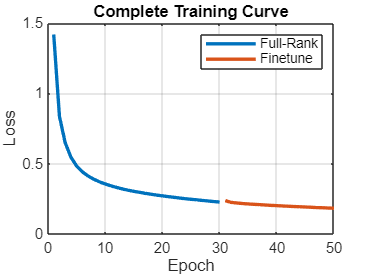

conf_mat = confusionmat(y_test, pred');

%% ===============================
% PLOTS
% ===============================

figure;
plot(loss_hist,'LineWidth',2); hold on;
plot(epochs + (1:finetune_epochs), ...
     finetune_loss_hist,'LineWidth',2);
legend('Full-Rank','Finetune');
xlabel('Epoch');
ylabel('Loss');
grid on;
title('Complete Training Curve');

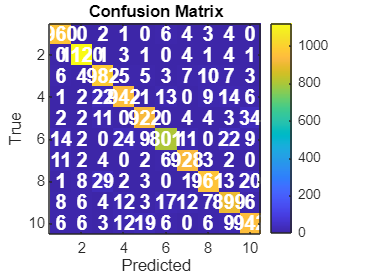


figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted');
ylabel('True');
title('Confusion Matrix');
axis square;

for i = 1:size(conf_mat,1)
    for j = 1:size(conf_mat,2)
        text(j, i, num2str(conf_mat(i,j)), ...
            'HorizontalAlignment','center', ...
            'Color','white', ...
            'FontSize',12, ...
            'FontWeight','bold');
    end
end

%% ==========================================
% MODEL COMPLEXITY ANALYSIS
% ==========================================

fprintf('\n================ MODEL COMPLEXITY ANALYSIS ================\n');


================ MODEL COMPLEXITY ANALYSIS ================



% ----------- RANKS BEFORE PRUNING -----------
rank_before = [r1 r2 r3];

% ----------- RANKS AFTER PRUNING ------------
rank_after = [length(alpha1), length(alpha2), length(alpha3)];

fprintf('\nRanks BEFORE pruning:  [%d  %d  %d]\n', rank_before);


Ranks BEFORE pruning:  [128  64  10]


fprintf('Ranks AFTER pruning:   [%d  %d  %d]\n', rank_after);

Ranks AFTER pruning:   [76  38  7]



% ============================================================
% PARAMETER COUNT
% ============================================================

% ---- Before pruning (Full-rank SVD parameterization)
params_before = ...
    (d1*r1 + d0*r1 + r1) + ...
    (d2*r2 + d1*r2 + r2) + ...
    (d3*r3 + d2*r3 + r3);

% ---- After pruning
r1p = rank_after(1);
r2p = rank_after(2);
r3p = rank_after(3);

params_after = ...
    (d1*r1p + d0*r1p + r1p) + ...
    (d2*r2p + d1*r2p + r2p) + ...
    (d3*r3p + d2*r3p + r3p);

fprintf('\nParameters BEFORE pruning: %d\n', params_before);


Parameters BEFORE pruning: 129966


fprintf('Parameters AFTER pruning:  %d\n', params_after);

Parameters AFTER pruning:  77247



compression_ratio = params_before / params_after;
fprintf('Compression Ratio: %.2fx\n', compression_ratio);

Compression Ratio: 1.68x



% ============================================================
% FLOPs COMPUTATION (Forward Pass Only)
% ============================================================

% For one sample:
% SVD layer FLOPs ≈ 2*d_in*r + 2*d_out*r
% (V'X + U*(...) multiplications)

% -------- BEFORE PRUNING --------
flops_before = ...
    (2*d0*r1 + 2*d1*r1) + ...
    (2*d1*r2 + 2*d2*r2) + ...
    (2*d2*r3 + 2*d3*r3);

% -------- AFTER PRUNING --------
flops_after = ...
    (2*d0*r1p + 2*d1*r1p) + ...
    (2*d1*r2p + 2*d2*r2p) + ...
    (2*d2*r3p + 2*d3*r3p);

fprintf('\nFLOPs BEFORE pruning (per sample): %d\n', flops_before);


FLOPs BEFORE pruning (per sample): 259528


fprintf('FLOPs AFTER pruning  (per sample): %d\n', flops_after);

FLOPs AFTER pruning  (per sample): 154252



flops_reduction = (1 - flops_after/flops_before) * 100;
fprintf('FLOPs Reduction: %.2f%%\n', flops_reduction);

FLOPs Reduction: 40.56%



fprintf('===========================================================\n\n');

toc

Elapsed time is 223.143363 seconds.


# **SVD training (Fashion MNIST)**

tic
X_train = loadMNISTImages('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\train-images-idx3-ubyte');
y_train = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\train-labels-idx1-ubyte');
X_test  = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\t10k-images-idx3-ubyte");
y_test  = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\t10k-labels-idx1-ubyte');
Y_train = oneHotEncode(y_train,10);
Y_test  = oneHotEncode(y_test,10);
rng(1);
%Layer Dimensions
d0 = 784; %Input layer
d1 = 128; %First hidden layer
d2 = 64; %Second hidden layer
d3 = 10; %Output layer

r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0); 
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0); 
[V3,~] = qr(randn(d2,r3),0); 
alpha3 = randn(r3,1);


% TRAINING PARAMETERS


epochs = 30;
batch_size = 128;
lr = 1e-3;
lambda_orth = 1.0;
lambda_sparse = 1e-3;

N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);


% FULL-RANK SVD TRAINING

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;

    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1:b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);

        s1 = exp(alpha1); S1 = diag(sqrt(s1));
        s2 = exp(alpha2); S2 = diag(sqrt(s2));
        s3 = exp(alpha3); S3 = diag(sqrt(s3));

        % Forward
        H1 = S1*(V1'*X); Z1 = U1*S1*H1; A1 = max(0,Z1);
        H2 = S2*(V2'*A1); Z2 = U2*S2*H2; A2 = max(0,Z2);
        H3 = S3*(V3'*A2); Z3 = U3*S3*H3;

        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3)./sum(exp(Z3),1);

        CE = -sum(sum(Y.*log(Yhat+1e-8)))/m;

        Orth = norm(U1'*U1-eye(size(U1,2)),'fro')^2 + ...
               norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
               norm(U2'*U2-eye(size(U2,2)),'fro')^2 + ...
               norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
               norm(U3'*U3-eye(size(U3,2)),'fro')^2 + ...
               norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + ...
                 norm(s2,1)/norm(s2,2) + ...
                 norm(s3,1)/norm(s3,2);

        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;

        %% Backprop (Complete)
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;

        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*(sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3);

        dA2 = V3*(S3*dH3); dZ2 = dA2.*(Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;

        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*(sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2);

        dA1 = V2*(S2*dH2); dZ1 = dA1.*(Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;

        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*(sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1);

        % Update
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);

        U1 = U1 - lr*dU1; V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2; V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3; V3 = V3 - lr*dV3;
    end

    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n',epoch,loss_hist(epoch));
end

Epoch 1 | Loss 1.4924
Epoch 2 | Loss 1.0047
Epoch 3 | Loss 0.8253
Epoch 4 | Loss 0.7243
Epoch 5 | Loss 0.6635
Epoch 6 | Loss 0.6230
Epoch 7 | Loss 0.5942
Epoch 8 | Loss 0.5740
Epoch 9 | Loss 0.5546
Epoch 10 | Loss 0.5418
Epoch 11 | Loss 0.5268
Epoch 12 | Loss 0.5168
Epoch 13 | Loss 0.5084
Epoch 14 | Loss 0.4993
Epoch 15 | Loss 0.4937
Epoch 16 | Loss 0.4855
Epoch 17 | Loss 0.4801
Epoch 18 | Loss 0.4742
Epoch 19 | Loss 0.4682
Epoch 20 | Loss 0.4643
Epoch 21 | Loss 0.4587
Epoch 22 | Loss 0.4561
Epoch 23 | Loss 0.4519
Epoch 24 | Loss 0.4479
Epoch 25 | Loss 0.4438
Epoch 26 | Loss 0.4394
Epoch 27 | Loss 0.4381
Epoch 28 | Loss 0.4338
Epoch 29 | Loss 0.4335
Epoch 30 | Loss 0.4273




% ENERGY-BASED PRUNING

energy_thresh = 0.99;



[U1,V1,alpha1] = prune_layer(U1,V1,alpha1,energy_thresh);
[U2,V2,alpha2] = prune_layer(U2,V2,alpha2,energy_thresh);
[U3,V3,alpha3] = prune_layer(U3,V3,alpha3,energy_thresh);


% LOW-RANK FINETUNING

lambda_sparse = 0;      % TURN OFF SPARSITY TO PREVENT OVERFITTING
finetune_epochs = 20;
lr = 5e-4;

finetune_loss_hist = zeros(finetune_epochs,1);

for epoch = 1:finetune_epochs
    perm = randperm(N);
    epoch_loss = 0;

    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1:b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);

        s1 = exp(alpha1); S1 = diag(sqrt(s1));
        s2 = exp(alpha2); S2 = diag(sqrt(s2));
        s3 = exp(alpha3); S3 = diag(sqrt(s3));

        % Forward
        H1 = S1*(V1'*X); Z1 = U1*S1*H1; A1 = max(0,Z1);
        H2 = S2*(V2'*A1); Z2 = U2*S2*H2; A2 = max(0,Z2);
        H3 = S3*(V3'*A2); Z3 = U3*S3*H3;

        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3)./sum(exp(Z3),1);

        CE = -sum(sum(Y.*log(Yhat+1e-8)))/m;

        % Orthogonality regularizer
        Orth = norm(U1'*U1-eye(size(U1,2)),'fro')^2 + ...
               norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
               norm(U2'*U2-eye(size(U2,2)),'fro')^2 + ...
               norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
               norm(U3'*U3-eye(size(U3,2)),'fro')^2 + ...
               norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        loss = CE + lambda_orth*Orth;
        epoch_loss = epoch_loss + loss;

        %% Backprop (same as full training but no sparse term)

        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;

        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));

        dA2 = V3*(S3*dH3); dZ2 = dA2.*(Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;

        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));

        dA1 = V2*(S2*dH2); dZ1 = dA1.*(Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;

        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));

        % Update
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);

        U1 = U1 - lr*dU1; V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2; V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3; V3 = V3 - lr*dV3;
    end

    finetune_loss_hist(epoch) = epoch_loss/num_batches;

    fprintf('Finetune Epoch %d | Loss %.4f\n', ...
            epoch, finetune_loss_hist(epoch));
end

Finetune Epoch 1 | Loss 0.4355
Finetune Epoch 2 | Loss 0.4219
Finetune Epoch 3 | Loss 0.4160
Finetune Epoch 4 | Loss 0.4113
Finetune Epoch 5 | Loss 0.4084
Finetune Epoch 6 | Loss 0.4054
Finetune Epoch 7 | Loss 0.4032
Finetune Epoch 8 | Loss 0.4010
Finetune Epoch 9 | Loss 0.3988
Finetune Epoch 10 | Loss 0.3969
Finetune Epoch 11 | Loss 0.3944
Finetune Epoch 12 | Loss 0.3944
Finetune Epoch 13 | Loss 0.3929
Finetune Epoch 14 | Loss 0.3908
Finetune Epoch 15 | Loss 0.3894
Finetune Epoch 16 | Loss 0.3881
Finetune Epoch 17 | Loss 0.3870
Finetune Epoch 18 | Loss 0.3851
Finetune Epoch 19 | Loss 0.3846
Finetune Epoch 20 | Loss 0.3833


%% ===============================
% TEST EVALUATION
% ===============================

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));

H1 = S1*(V1'*X_test); A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);     A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);     Z3 = U3*S3*H3;

[~,pred] = max(Z3,[],1);
pred = pred - 1;

acc = mean(pred'==y_test)*100;
fprintf('\nFinal Test Accuracy: %.2f%%\n',acc);


Final Test Accuracy: 84.64%


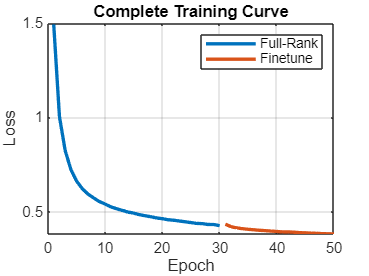

conf_mat = confusionmat(y_test, pred');

%% ===============================
% PLOTS
% ===============================

figure;
plot(loss_hist,'LineWidth',2); hold on;
plot(epochs + (1:finetune_epochs), ...
     finetune_loss_hist,'LineWidth',2);
legend('Full-Rank','Finetune');
xlabel('Epoch');
ylabel('Loss');
grid on;
title('Complete Training Curve');

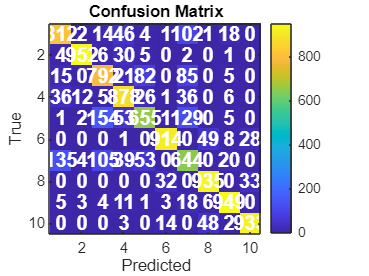


figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted');
ylabel('True');
title('Confusion Matrix');
axis square;

for i = 1:size(conf_mat,1)
    for j = 1:size(conf_mat,2)
        text(j, i, num2str(conf_mat(i,j)), ...
            'HorizontalAlignment','center', ...
            'Color','white', ...
            'FontSize',12, ...
            'FontWeight','bold');
    end
end

%% ==========================================
% MODEL COMPLEXITY ANALYSIS
% ==========================================

fprintf('\n================ MODEL COMPLEXITY ANALYSIS ================\n');


================ MODEL COMPLEXITY ANALYSIS ================



% ----------- RANKS BEFORE PRUNING -----------
rank_before = [r1 r2 r3];

% ----------- RANKS AFTER PRUNING ------------
rank_after = [length(alpha1), length(alpha2), length(alpha3)];

fprintf('\nRanks BEFORE pruning:  [%d  %d  %d]\n', rank_before);


Ranks BEFORE pruning:  [128  64  10]


fprintf('Ranks AFTER pruning:   [%d  %d  %d]\n', rank_after);

Ranks AFTER pruning:   [75  40  7]



% ============================================================
% PARAMETER COUNT
% ============================================================

% ---- Before pruning (Full-rank SVD parameterization)
params_before = ...
    (d1*r1 + d0*r1 + r1) + ...
    (d2*r2 + d1*r2 + r2) + ...
    (d3*r3 + d2*r3 + r3);

% ---- After pruning
r1p = rank_after(1);
r2p = rank_after(2);
r3p = rank_after(3);

params_after = ...
    (d1*r1p + d0*r1p + r1p) + ...
    (d2*r2p + d1*r2p + r2p) + ...
    (d3*r3p + d2*r3p + r3p);

fprintf('\nParameters BEFORE pruning: %d\n', params_before);


Parameters BEFORE pruning: 129966


fprintf('Parameters AFTER pruning:  %d\n', params_after);

Parameters AFTER pruning:  76720



compression_ratio = params_before / params_after;
fprintf('Compression Ratio: %.2fx\n', compression_ratio);

Compression Ratio: 1.69x



% ============================================================
% FLOPs COMPUTATION (Forward Pass Only)
% ============================================================

% For one sample:
% SVD layer FLOPs ≈ 2*d_in*r + 2*d_out*r
% (V'X + U*(...) multiplications)

% -------- BEFORE PRUNING --------
flops_before = ...
    (2*d0*r1 + 2*d1*r1) + ...
    (2*d1*r2 + 2*d2*r2) + ...
    (2*d2*r3 + 2*d3*r3);

% -------- AFTER PRUNING --------
flops_after = ...
    (2*d0*r1p + 2*d1*r1p) + ...
    (2*d1*r2p + 2*d2*r2p) + ...
    (2*d2*r3p + 2*d3*r3p);

fprintf('\nFLOPs BEFORE pruning (per sample): %d\n', flops_before);


FLOPs BEFORE pruning (per sample): 259528


fprintf('FLOPs AFTER pruning  (per sample): %d\n', flops_after);

FLOPs AFTER pruning  (per sample): 153196



flops_reduction = (1 - flops_after/flops_before) * 100;
fprintf('FLOPs Reduction: %.2f%%\n', flops_reduction);

FLOPs Reduction: 40.97%



fprintf('===========================================================\n\n');

toc

Elapsed time is 204.093031 seconds.
